# Filter Test (LPF & HPF)

## Test Signals

addpath(genpath('Test Signals'));
[dirac, fs] = audioread('diracTest.wav');
[ess, fs] = audioread('sineSweep.wav');
[pink_noise, fs] = audioread('pinkNoise.wav');

## Dirac Delta

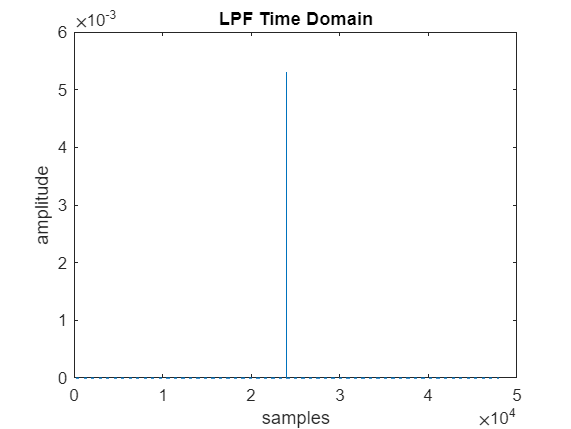

buffer_length = 480;
fs = 44100;
Q = 1;
gain = 1;

lpf = Filter(fs, 1000, Q, gain, 'Lowpass');
hpf = Filter(fs, 5000, Q, gain, 'Highpass');

% Set variables for buffering and loop through the test signal
% LPF
num_buffs = ceil(length(dirac) / buffer_length);
dirac_out = zeros(size(dirac));

for b = 1:num_buffs
    start_ind = (b - 1) * buffer_length + 1;
    end_ind = min(start_ind + buffer_length - 1, length(dirac));
    buff = dirac(start_ind:end_ind, :); 
    processed_buff = applyFilter(lpf, buff);
    dirac_out(start_ind:end_ind, :) = processed_buff;
end

figure(1);
plot(dirac_out);
title('LPF Time Domain');
xlabel('samples');
ylabel('amplitude');

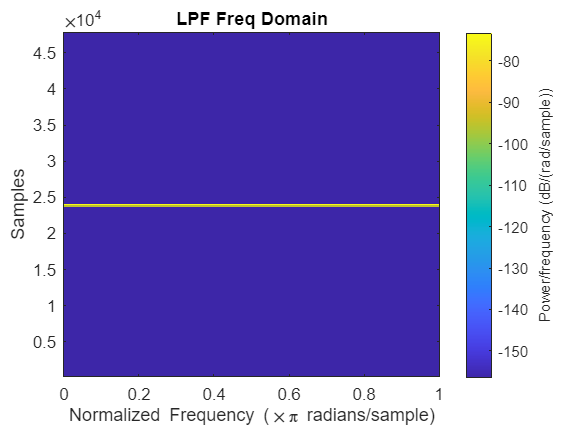



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(2);
spectrogram(dirac_out, hamming(win_length), overlap_length, nfft);
title('LPF Freq Domain');

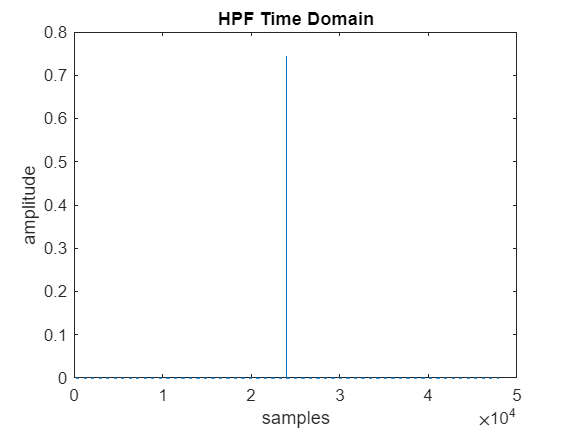


% HPF

for b = 1:num_buffs
    start_ind = (b - 1) * buffer_length + 1;
    end_ind = min(start_ind + buffer_length - 1, length(dirac));
    buff = dirac(start_ind:end_ind, :); 
    processed_buff = applyFilter(hpf, buff);
    dirac_out(start_ind:end_ind, :) = processed_buff;
end

figure(3);
plot(dirac_out);
title('HPF Time Domain');
xlabel('samples');
ylabel('amplitude');

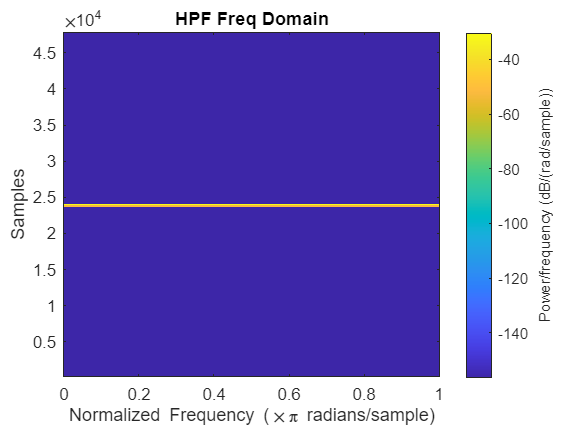



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(4);
spectrogram(dirac_out, hamming(win_length), overlap_length, nfft);
title('HPF Freq Domain');

## ESS

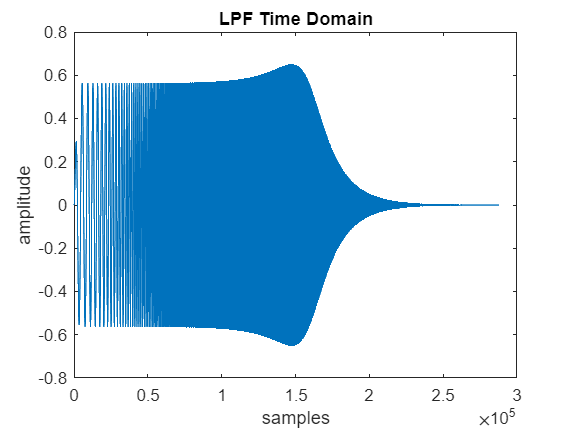

% Set variables for buffering and loop through the test signal
% LPF
ess_out = lpf.applyFilter(ess);

figure(5);
plot(ess_out);
title('LPF Time Domain');
xlabel('samples');
ylabel('amplitude');

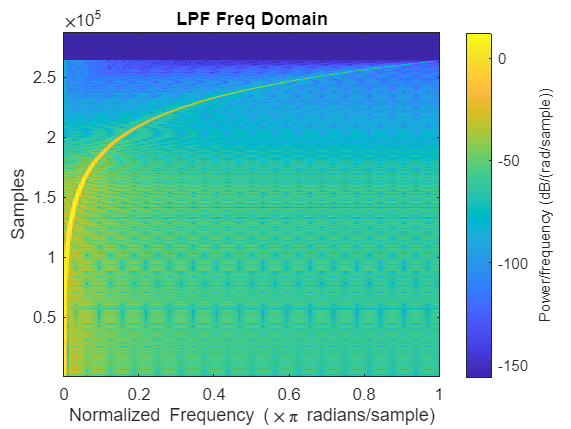



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(6);
spectrogram(ess_out, hamming(win_length), overlap_length, nfft);
title('LPF Freq Domain');

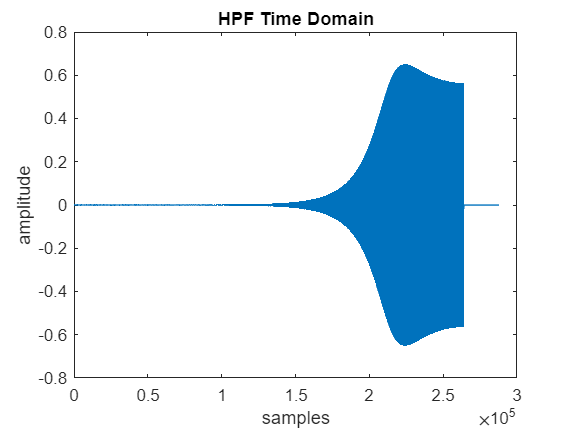


% HPF

ess_out = hpf.applyFilter(ess);

figure(7);
plot(ess_out);
title('HPF Time Domain');
xlabel('samples');
ylabel('amplitude');

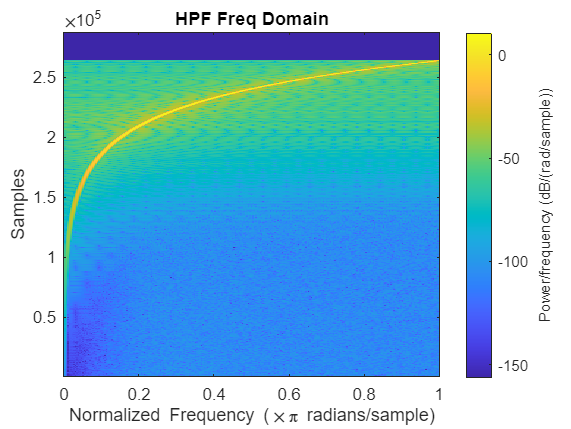



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(8);
spectrogram(ess_out, hamming(win_length), overlap_length, nfft);
title('HPF Freq Domain');

## Pink Noise

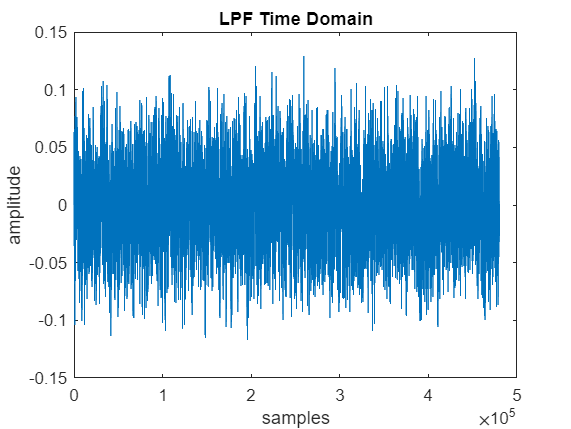

% Set variables for buffering and loop through the test signal
% LPF
num_buffs = ceil(length(pink_noise) / buffer_length);
pink_noise_out = zeros(size(pink_noise));

for b = 1:num_buffs
    start_ind = (b - 1) * buffer_length + 1;
    end_ind = min(start_ind + buffer_length - 1, length(pink_noise));
    buff = pink_noise(start_ind:end_ind, :); 
    processed_buff = applyFilter(lpf, buff);
    pink_noise_out(start_ind:end_ind, :) = processed_buff;
end

figure(5);
plot(pink_noise_out);
title('LPF Time Domain');
xlabel('samples');
ylabel('amplitude');

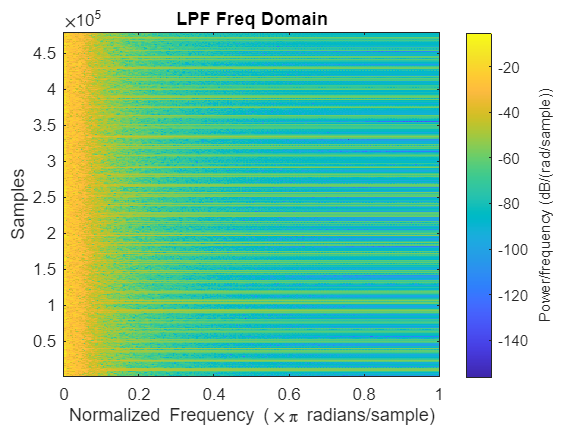



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(6);
spectrogram(pink_noise_out, hamming(win_length), overlap_length, nfft);
title('LPF Freq Domain');

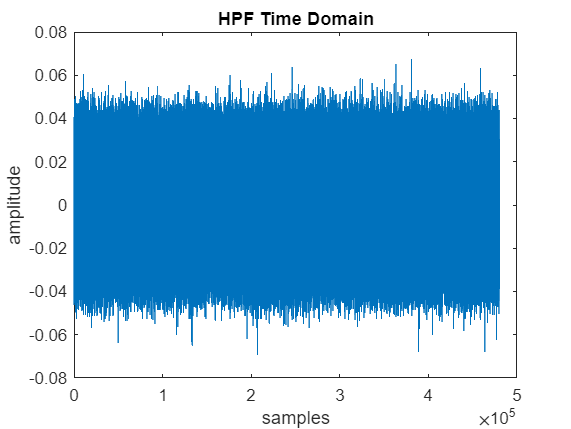


% HPF

for b = 1:num_buffs
    start_ind = (b - 1) * buffer_length + 1;
    end_ind = min(start_ind + buffer_length - 1, length(pink_noise));
    buff = pink_noise(start_ind:end_ind, :); 
    processed_buff = applyFilter(hpf, buff);
    pink_noise_out(start_ind:end_ind, :) = processed_buff;
end

figure(7);
plot(pink_noise_out);
title('HPF Time Domain');
xlabel('samples');
ylabel('amplitude');

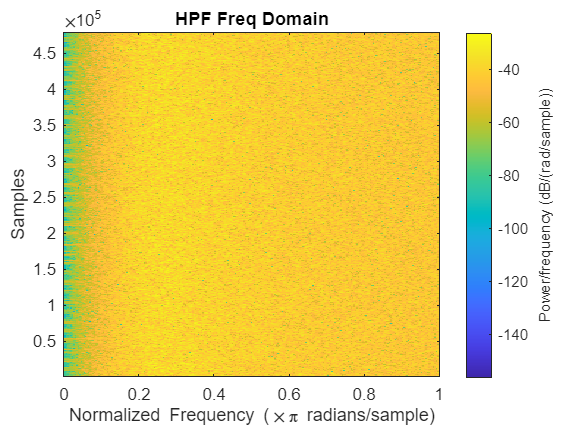



win_length = buffer_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(8);
spectrogram(pink_noise_out, hamming(win_length), overlap_length, nfft);
title('HPF Freq Domain');